# Estimators Project - Magnetic Levitation

**Zeic Beniamin**

## **Lab 1 - Nonlinear Models**

The system for this project consists of an electromagnet and a ball. The control requirement will be to keep the ball in a steady position. 

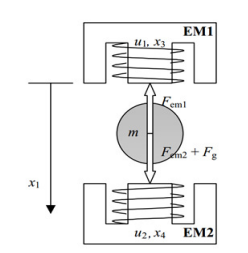

The state space considered will have the following values with physical meaning:

x1 - position of the ball

x2 - velocity of the ball

x3 - intensity of the current passing through coil

The input will be:

u - voltage through the coil

### 1. Simulate the system with initial conditions, no input

The system was simulated with zero initial conditions and zero as input.

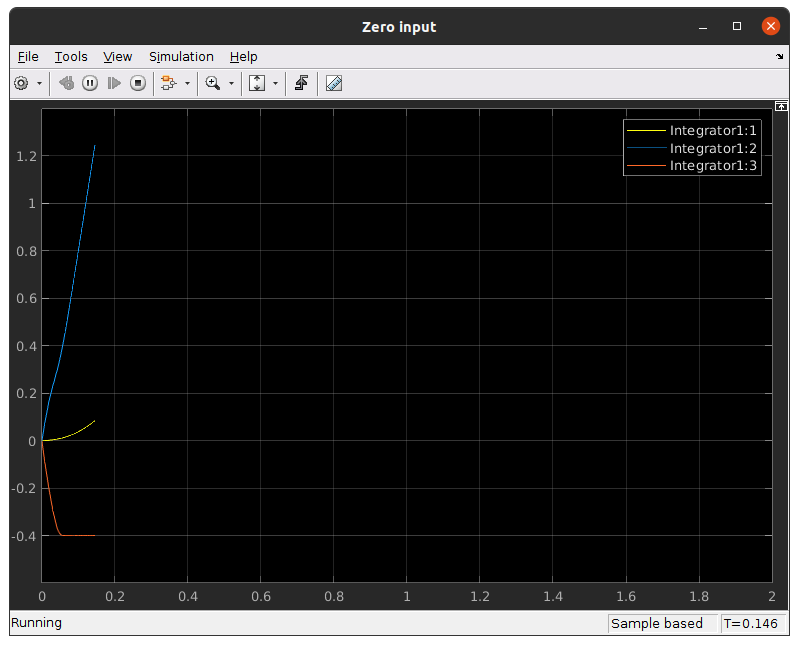

As can be seen, the velocity (blue trace) rapidly tends towards infinity (the ball is basically falling free, since there is no voltage fed through the coil).

### 2. Simulate the system with initial conditions, different non-zero inputs

With a fixed voltage signal of 0.231, the velocity of the ball initially decreases, then it increases towards infinity. This is a sign that the inductance of the coil managed to temporarily counteract the effect that the gravity had over the ball, but since the system is an open-loop one, the ball falled freely afterwards, since the voltage through the coil is uncontrollable, thus the inductance is constant.

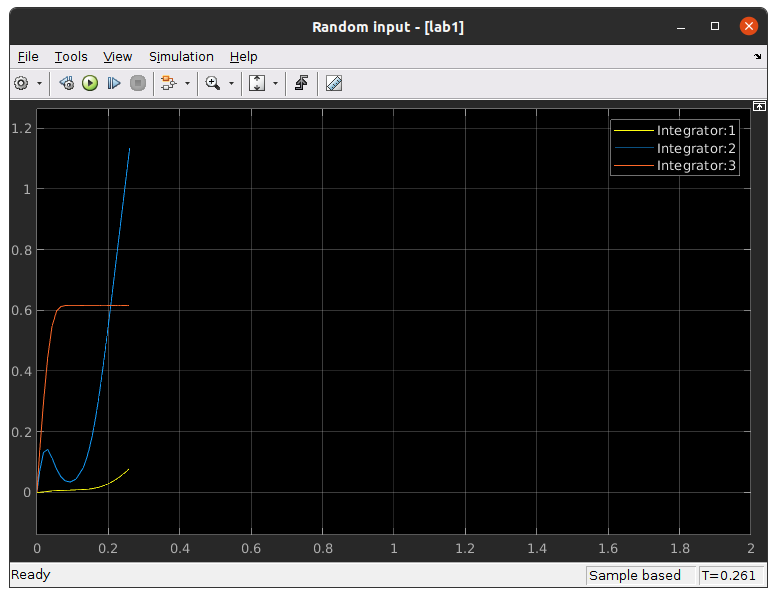

Tests with constant voltages above 0.231 result in a rapidly decreasing ball distance, until it reaches negative values (impossible in a real scenario). Tests with constant voltages under 0.231 result in a rapidly growing ball distance (i.e. the ball is falling freely).

### 3. Simulating with zero initial conditions, non-zero input, distance limited to positive values

Limiting the distance between the ball and the electromagnet to positive values gives the results plotted below:

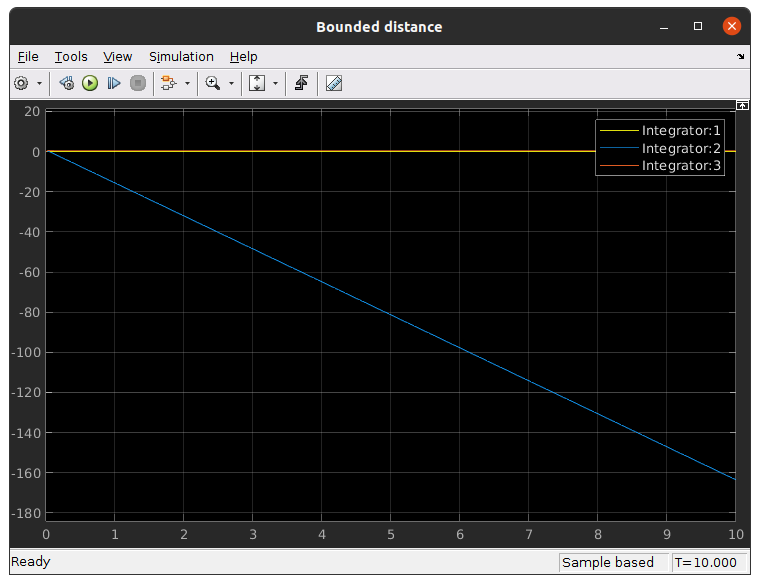

## **Lab 2 - Linear Model, State-Feedback Control, Observer Design**

% System parameters
FemP1 = 0.017521;
FemP2 = 0.0058231;

ci = -0.4;
ki = 4.4;
m = 0.016;
g = 9.81;

fiP1 = 1.4142e-4;
fiP2 = 4.5626e-3;

### **Computing the equilibrium point**

% Set the distance for which to compute the equilibrium point
% Distance between ball an upper coil
x10 = 0.01; % meters
% Initial speed set to zero
x20 = 0;
% Compute x03 from the second equation from equation set (9)
x30 = sqrt((g * 2 * m * FemP2) / (FemP1 * exp(-x10/FemP2)));

% Initial conditions vector
x0 = [x10; x20; x30];
% Use (11) to compute u0
u0 = (x30 - ci)/ki;

### **Calculate the linearization of x2 and x3**

% The linearization formulas below were obtained by linearinzing around the
% point (x10; x20; x30; u0);

% Frequently appearing ratio
fem_ratio = FemP1/(FemP2 * 2 * m);

x2_lin_x1_coeff = - x30^2 * fem_ratio * (-1) * exp(-x10 / FemP2)/FemP2;
x2_lin_x3_coeff = - 2 * x30 * fem_ratio * exp(-x10 / FemP2);

x3_lin_x3_coeff = - fiP2/fiP1 * exp(x10/fiP2);

u_lin_x3_coeff = fiP2/fiP1 * exp(x10/fiP2) * ki;

A = [0                  1       0;
     x2_lin_x1_coeff    0       x2_lin_x3_coeff;
     0                  0       x3_lin_x3_coeff];

B = [0;
     0;
     u_lin_x3_coeff];

### **Controllability matrix & state feedback**

PC = [B, A*B, A^2*B];
rank(PC) % Rank of controlabillity matrix is 3, so we can calculate state feedback gain

ans = 3

% State feedback gain using pole placement
poles = [-20 -41 -100];
K = place(A, B, poles);
% K = place(A, B, [-40, -41, -43]);

Simulation with dx = [0.01; 0; 0]

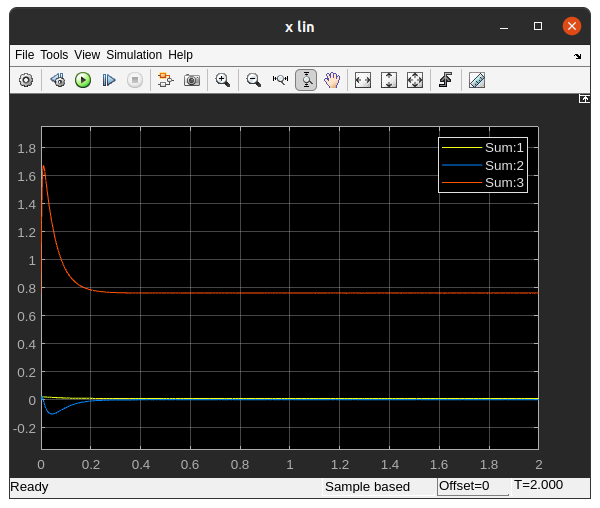

Although not visible in the graph, the steady state value for position is 0.01, which equals the initial value.

### **Observability matrix **

C = [1 1 0]; % Suppose we cannot access the last state
PO = [C; C * A; C * A^2];
rank(PO) % Rank of observability matrix = 3, so we can calculate observer

ans = 3

% Place the poles
L = place(A', C', poles)'

L = 1.0e+03 *

    0.0012
   -0.1289
   -1.6973


## **Lab 3 - Nonlinear Model, State-Feedback Control, Observer Design**

**The error is not converging to zero**

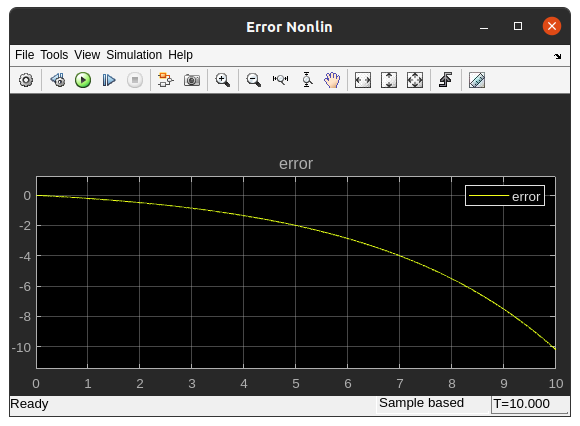

## **Lab 4 - Discrete-Time Linear Model, Control and Estimation**

% Discretization of linear system
Ts = 1e-3;
Ad = eye(3) + Ts .* A

Ad =     1.0000    0.0010         0
    1.6847    1.0000   -0.0257
         0         0    0.7112


Bd = Ts.*B

Bd =          0
         0
    1.2706


% Controllability matrix
Pcd = [Bd Ad*Bd Ad^2 * Bd];
rank(Pcd)

ans = 3

% Discrete controller
eig(Ad); % Unstable
poles = [-.1, -.2, -.3];
Kd = place(Ad, Bd, poles);

% Observability matrix
Pod =  [C; C*Ad; C*Ad^2];
rank(Pod); % Observable
Ld = place(Ad', C', poles)';

### Linear model, state feedback and observer

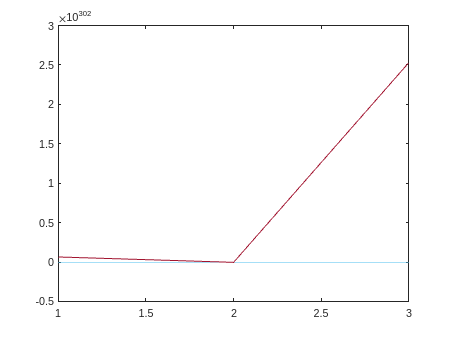

x_dot = x0;
x_est = [0; 0; 0];
store = [x_dot];
Dx = [0.01; 0; 1];
for k = 1:1000
    u = u0 - Kd * x_est(:,k);
    x_dot_prev = x_dot;

    x_dot = Ad * x_dot_prev + B * u + x_dot_prev;

    store = [store, x_dot];

    y_hat = C * x_dot;
    
    %Observer - linear
    u_obs = -Kd * x_est(:, k);
    y_est = C * x_est(:, k); % Get previously estimated output
    x_est_prev = x_est(:, k);
    x_est_hat = Ad * x_est_prev + B * u_obs;

    x_est = [x_est, (x_est_hat + Ld * (y_hat - y_est))];

end

figure 
plot(store - x_est)

### Non-linear model, state feedback and observer

x_dot = [0.01; 0; 0];
x_est = [0; 0; 0];
store = [x_dot];
Dx = [0.01; 0; 1];
for k = 1:1000 % simulate for 1 sec
    % Nonlinear system block
    u = u0 - Kd * x_est(:, k);
    x_dot_prev = x_dot;

    % x(k+1) = A * x(k) + B * x(k) + x(k)
    x_dot = [
        Ts * (x_dot_prev(2, 1) - x0(1,1) - Dx(1,1)) + x_dot_prev(1,1);
        Ts * (-x_dot_prev(3,1)^2 * FemP1/(FemP2 * 2 * m)) * exp( -x_dot_prev(1,1)/FemP2 ) + g - x0(2,1) - Dx(2,1) + x_dot_prev(2,1);
        Ts * ( 1/((fiP1/fiP2) * exp(-x_dot_prev(1,1)/fiP2)) * (ki * u + ci - x_dot_prev(3,1) - x0(3,1) - Dx(3,1))) + x_dot_prev(3,1)
    ];

    store = [store, x_dot];
    y_hat = C * x_dot;

    % Observer block - nonlinear
    u_obs = -Kd * x_est(:, k);
    y_est = C * x_est(:, k);
    x_est_prev = x_est(:, k);
    x_est_hat = [
        Ts * x_est_prev(2,1) + x_est_prev(1,1);
        Ts * (-(x_est_prev(3,1)^2) * FemP1/(FemP2*2*m) * exp(-x_est_prev(1,1)/FemP2) + g) + x_est_prev(2,1);
        Ts * (1/((fiP1/fiP2) * exp(-x_est_prev(1,1)/fiP2)) * (ki*u_obs + ci - x_est_prev(3,1))) + x_est_prev(3,1)
    ];

    x_est = [x_est, (x_est_hat + Ld * (y_hat - y_est))];
end
figure
plot(store - x_est) % Error diverges

## **Lab 6 - Kalman Filter Design**

alpha = 0.5;
beta = 0.01;
x_dot = [0.01; 0; 0];
x_est = [0; 0; 0];
P = 1e3 * eye(3);
Q = 1e-2 * alpha * eye(3);
R = 1e3 * beta * eye(1);

for k = 2:100
    % Add noise
    w = 1e-3 * randn(3,1);
    v = 1e-3 * randn(1,1);

    u = -Kd * x_est(:, k-1);

    x_dot(:, k) = Ad * x_dot(:, k-1) + Bd * u + w;
    y(:, k) = C * x_dot(:, k) + v;

    x_pred = Ad * x_est(:, k-1) + Bd * u;
    P_pred = Ad * P * Ad + Q;
    K = P_pred * C' * inv(C * P_pred * C' + R);

    x_est(:, k) = x_pred + K * (y(:, k) - C * x_pred);
    P = (eye(3) - K * C) * P_pred;
end
figure

plot(x_dot')
legend("x1", "x2", "x3")
figure
plot(x_est');
legend("x1", "x2", "x3")

## **Lab 7 - Extended Kalman Filter Design**

x_dot = [1e-7; 0; 0] + x0;
x_hat = x0;
u = u0;
alpha = 0.5;
beta = 0.01;
P = 1e5 * eye(3);
Q = 1e-7 * alpha * eye(3);
R = 1e-7 * beta * eye(1);

syms x1 x2 x3 u;
f(x1, x2, x3, u) = [
    Ts * x2 + x1;
    Ts * (-(x3^2) * FemP1/(FemP2 * 2 * m) * exp(-x1/FemP2) + g) + x2;
    Ts * (1/(fiP1/fiP2 * exp(-x1/fiP2) * (ki * u - ci - x3)) + x3);
];

F = jacobian(f, [x1, x2, x3]);
f_eval = eval(f(x_dot(1,1), x_dot(2,1), x_dot(3,1), u));
Fk = eval(F(x_hat(1,1), x_hat(2,1), x_hat(3,1), u));

for k = 2:50
    w = 1e-7 * randn(3,1);
    v = 1e-7 * randn(1,1);

    % k
    u = u0 - Kd * (x_hat(:, k-1) - x0);

    f_eval = eval(f(x_dot(1,k-1), x_dot(2,k-1), x_dot(3,k-1), u));

    x_dot(:, k) = f_eval + w;
    y(:, k) = C * x_dot(:, k) + v;

    x_pred = eval(f(x_hat(1,k-1), x_hat(2,k-1), x_hat(3,k-1), u));

    Fk = eval(F(x_hat(1,k-1), x_hat(2,k-1), x_hat(3,k-1), u));

    P_pred = Fk(:, 1:3) * P * Fk(:, 1:3)' + Q;
    K = P_pred * C' *inv(C * P_pred * C' + R);

    x_hat(:, k) = x_pred + K * (y(:, k) - C * x_pred);
    P = (eye(3) - K * C) * P_pred;
end

figure;
hold on;
plot(x_dot(1,:)');
plot(x_hat(1,:)');

## **Lab 8 - Unknown Input Observer Design**

### Continuous

E = [1; 0; 0]; % Consider that the posiiton is the affected measurement;
d = 0.5;
Ae = [
    A E;
    zeros(1,3) 0];
Be = [
    B; 
    0
];
C = [1 1 0];
Ce = [C 0];

Poe = [Ce; Ce*Ae; Ce*(Ae^2); Ce*(Ae^3)];
rank(Poe); % Observable
eig(Ae); %Unstable
Le = place(Ae', Ce', [-1, -2, -3, -41])';

### Discrete

Pode = [Ce; Ce * Ade; Ce * Ade^2; Ce * Ade^3];

Unrecognized function or variable 'Ade'.

rank(Pode)

### Discrete system

Ade = eye(4) + Ts .* Ae;
Bde = Ts .* Be;
Pode = [Ce; Ce*Ade; Ce*Ade^2];
rank(Pode) % rank = 3
Lde = place(transpose(Ade), transpose(Ce), [-0.1, -0.2, -0.3, -.04])';



**Lab 9 - Unknown Input Decoupling Observer and Fault Detection**